**Task 1-3**


load GunshotDatabase.mat;
Threshold = 1;
L_temp = length(GunshotTemplate);
L_clips = length(GunshotClips);
L_o_clips = length(OutsiderClips);
[r1,c1]=size(GunshotClips);  
[r2,c2]=size(OutsiderClips); 

C1 = zeros(r1,L_clips-L_temp+1);
C2 = zeros(r2,L_o_clips-L_temp+1);

% sliding window operation for GunshotClips
for idx = 1:L_clips-L_temp+1    
    C1(:,idx) = GunshotTemplate*GunshotClips(:,idx:L_temp+idx-1)';
end

% sliding window operation for OutsiderClips
for idx = 1:L_o_clips-L_temp+1    
    C2(:,idx) = GunshotTemplate*OutsiderClips(:,idx:L_temp+idx-1)';
end

% max correlation for each row for GunshotClips and OutsiderClips
c3=max(C1,[],2); 
c4=max(C2,[],2);

% threshold comparison
y1=c3(c3>Threshold);
y2=c4(c4>Threshold);

% true positive and true negative values
ptr=length(y1)/r1

ptr = 0.9789

ntr=length(y2)/r2

ntr = 0.1039


% best detection for gunshot data
bestDetection=min(c3)

bestDetection = 0.0604


% for eliminating false positive alarms
falsePositives=max(c4)

falsePositives = 1.7568


% TASK # 2

%increasing threshold value decreases positive and negative true rate.
%decreasing threshold value increases positive and negative true rate

%Best detection of gunshot data is the minimum correlation that can be
%found in gunshot data and outsider clip. It is the threshold minimum value
%that can be thus detected.

%False positive is the maximum correlation that can be found between
%gunshot clips and outsider clips.It is thus the maximum threshold value
%after which you get a false positive.









**TASK # 3**

Threshold_vec=linspace(bestDetection, falsePositives,50);
true_positive=zeros(1,length(Threshold_vec));
false_positive=zeros(1,length(Threshold_vec));
for i=1:length(Threshold_vec)
    z1=c3(c3>Threshold_vec(i));
    z2=c4(c4>Threshold_vec(i));
    true_positive(i)=length(z1)/r1;
    false_positive(i)=length(z2)/r2;
end

display(true_positive);

true_positive =     0.9970    0.9970    0.9970    0.9970    0.9970    0.9970    0.9970    0.9970    0.9970    0.9970    0.9970    0.9970    0.9970    0.9970    0.9970    0.9970    0.9970    0.9970    0.9970    0.9970    0.9970    0.9970    0.9970    0.9970    0.9970    0.9940    0.9880    0.9819    0.9669    0.9398    0.8946    0.8765    0.8313    0.7741    0.7018    0.6536    0.5964    0.5392    0.5030    0.4759    0.4578    0.4157    0.3886    0.3554    0.3223    0.2922    0.2590    0.2319    0.2108    0.1867


display(false_positive);

false_positive =     0.7792    0.6883    0.5974    0.5325    0.4545    0.4286    0.3766    0.3506    0.2987    0.2727    0.2597    0.2338    0.2208    0.2078    0.1818    0.1818    0.1688    0.1688    0.1688    0.1558    0.1558    0.1429    0.1169    0.1169    0.1169    0.1039    0.1039    0.1039    0.1039    0.0909    0.0909    0.0909    0.0779    0.0649    0.0519    0.0519    0.0519    0.0519    0.0519    0.0519    0.0519    0.0519    0.0519    0.0519    0.0390    0.0260    0.0130    0.0130    0.0130         0


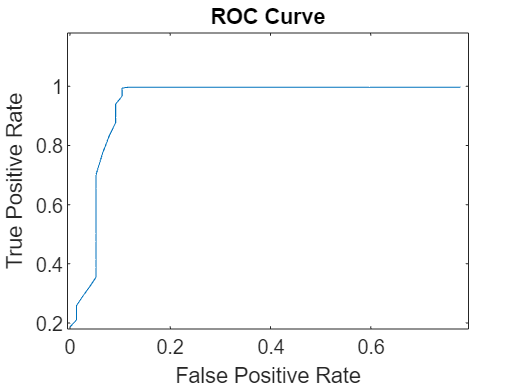



plot(false_positive,true_positive,'-');
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title('ROC Curve');

xlim([-0.005 0.795]);
ylim([0.18 1.18]);



clear;



**Task 4-6 ( majorly 4)**

load GunshotArraySignals.mat

d=0.1; % converted to m 
c=333; %speed of sound
delta_t_max=d/c % dtmax

delta_t_max = 3.0030e-04

Dmax=ceil(delta_t_max*fs) % Dmax when the d = 0.1

Dmax = 14


xl_1=GunshotArray1(1,:); % source should lie in 2nd quad 
xr_1=GunshotArray1(2,:);
xl_2=GunshotArray2(1,:); % source should lie in 1st quad 
xr_2=GunshotArray2(2,:);
xl_3=GunshotArray3(1,:); % source should lie in 1st quad
xr_3=GunshotArray3(2,:);

%C() represent correlation. 
C6 =zeros(1,Dmax);
C7 =zeros(1,Dmax);
C8 =zeros(1,Dmax);
C9 =zeros(1,Dmax);
C10 =zeros(1,Dmax);
C11 =zeros(1,Dmax);

for n=1:Dmax
    %1st track
    xdr_1=[zeros(1,n-1) xr_1(1:end-n+1)]; 
    xdl_1=[zeros(1,n-1) xl_1(1:end-n+1)];
    C6(n)=xl_1*xdr_1'; %sliding r on l
    C7(n)=xr_1*xdl_1'; %sliding l on r
    
    %2nd track
    xdr_2=[zeros(1,n-1) xr_2(1:end-n+1)];
    xdl_2=[zeros(1,n-1) xl_2(1:end-n+1)];
    C8(n)=xl_2*xdr_2'; %sliding r on l
    C9(n)=xr_2*xdl_2'; %sliding l on r
    
    %3rd track
    xdr_3=[zeros(1,n-1) xr_3(1:end-n+1)];
    xdl_3=[zeros(1,n-1) xl_3(1:end-n+1)];
    C10(n)=xl_3*xdr_3'; %sliding r on l
    C11(n)=xr_3*xdl_3'; %sliding l on r
end

%doxel_hck_2 "MAHK"
[Cmax1, idx1]=max(C6);  %setting right as delayed
[Cmax2, idx2]=max(C7); %setting left as delayed

[Cmax3, idx3]=max(C8);  %setting right as delayed
[Cmax4, idx4]=max(C9); %setting left as delayed

[Cmax5, idx5]=max(C10);  %setting right as delayed
[Cmax6, idx6]=max(C11);%setting left as delayed

%for track 1
if idx1 > idx2  % if delay in right is greater
    % Sound arrived from left
    dt1 = (idx1 - 1) / fs
    theta1 = (acos((dt1 * c) / d) * 180) / pi  %in degrees
else
    % Sound arrived from right
    dt1 = (idx2 - 1) / fs
    theta1 = 180 - ((acos((dt1 * c) / d) * 180) / pi)
end

dt1 = 1.1338e-04

theta1 = 112.1821


%for track 2 
if idx3 > idx4
    % Sound arrived from left
    dt2 = (idx3 - 1) / fs
    theta2 = (acos((dt2 * c) / d) * 180) / pi
else
    % Sound arrived from right
    dt2 = (idx4 - 1) / fs
    theta2 = 180 - ((acos((dt2 * c) / d) * 180) / pi)
end

dt2 = 6.8027e-05

theta2 = 76.9071


% for track 3
if idx5 > idx6
    % Sound arrived from left
    dt3 = (idx5 - 1) / fs
    theta3 = (acos((dt3 * c) / d) * 180) / pi
else
    % Sound arrived from right
    dt3 = (idx6 - 1) / fs
    theta3 = 180 - ((acos((dt3 * c) / d) * 180) / pi)
end

dt3 = 2.2676e-04

theta3 = 40.9657



clear;